import lib.*


all_spk = load("./mouse59/mouse59_grid_cell/day08-1117/s1/all_spk.mat");
pos_corr = load("./mouse59/mouse59_grid_cell/day08-1117/s1/m59_d8_s1_spks_pfield_pos_corr.mat");
pos = load("./mouse59/mouse59_grid_cell/day08-1117/s1/pos.mat");

尝试画图

all_spk.spks: 一行是一个细胞，每一个细胞spk的时间

all_spk.spks{1,1}

ans = 	1.0e+03 *

    1.5894
    1.5954
    1.5954
    1.5954
    1.5954
    1.5954
    1.5954
    1.5955
    1.5955
    1.5955


pos.pos: [time, x, y, ?]

pos.pos

ans = 	1.0e+03 *

    1.5905   -0.0084    0.0059    0.0012
    1.5905   -0.0084    0.0059    0.0012
    1.5905   -0.0084    0.0059    0.0012
    1.5906   -0.0085    0.0055    0.0014
    1.5906   -0.0085    0.0057       NaN
    1.5906   -0.0086    0.0054    0.0013
    1.5906   -0.0087    0.0054    0.0012
    1.5906   -0.0088    0.0053    0.0012
    1.5906   -0.0089    0.0054    0.0012
    1.5907   -0.0091    0.0054    0.0011


pos_corr.Corrs{1,1}

ans =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN 

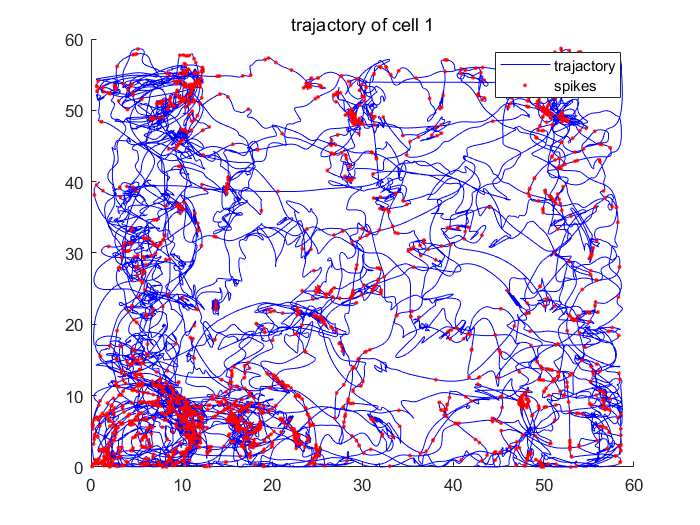

rm = lib.Rate_Matrix(1,pos.pos(:,1),pos.pos(:,2),pos.pos(:,3),all_spk.spks{1,1});
lib.Rate_Matrix.plot_trajactory(rm)

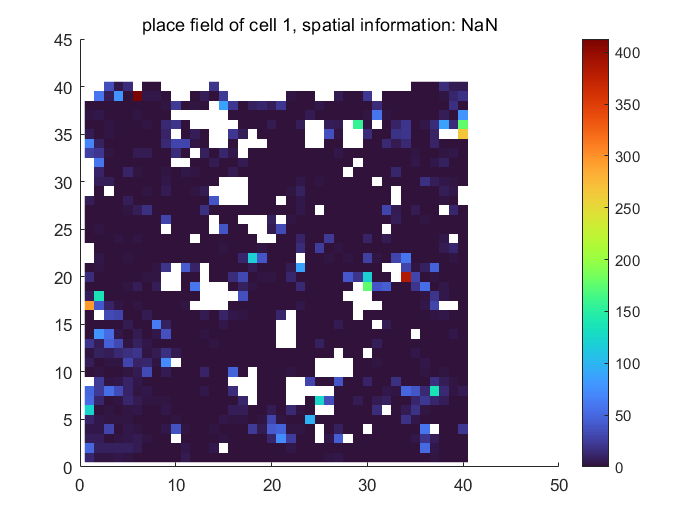

rm.naive_rm(40);
lib.Rate_Matrix.plot_rate_map(rm, true)

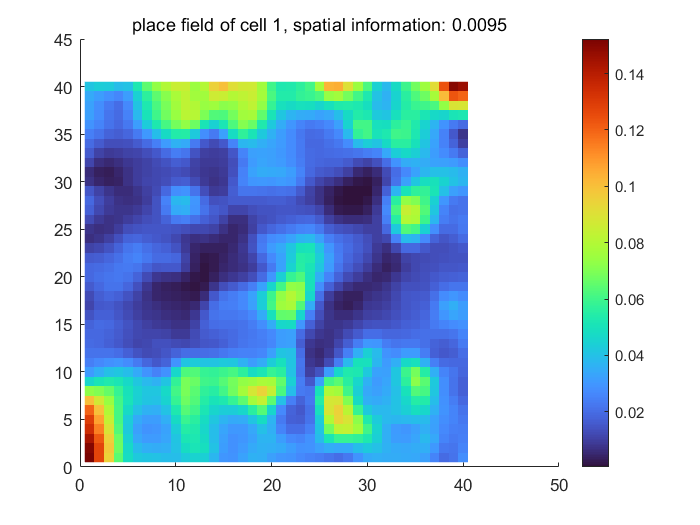

rm.gauss_rm(40);
lib.Rate_Matrix.plot_rate_map(rm)

rm.cal_auto_corr();
lib.Rate_Matrix.plot_trajactory(rm)

lib.Rate_Matrix.plot_rate_map(rm)

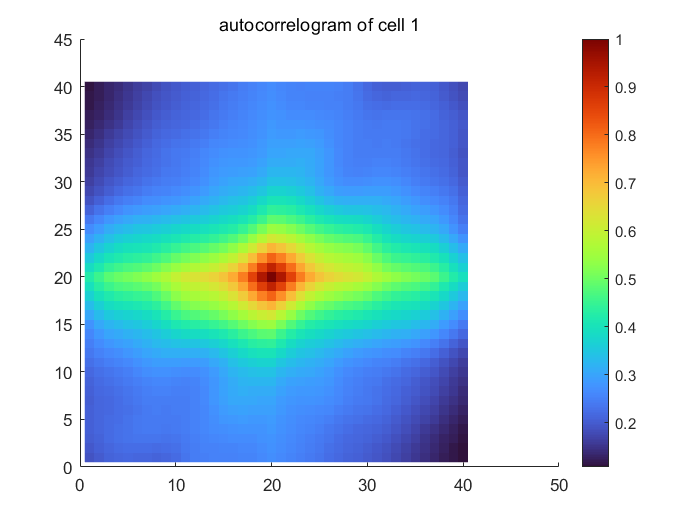

lib.Rate_Matrix.plot_auto_corr(rm)

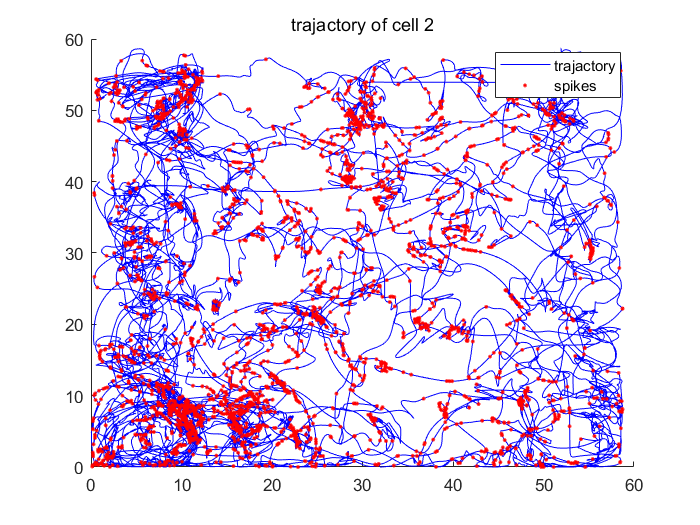

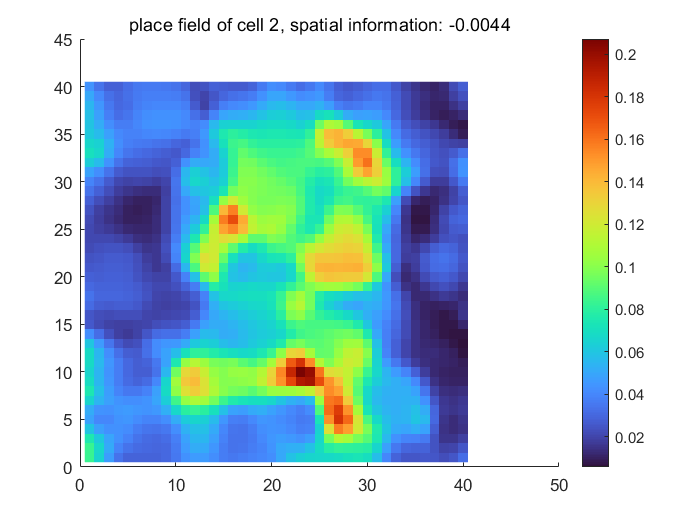

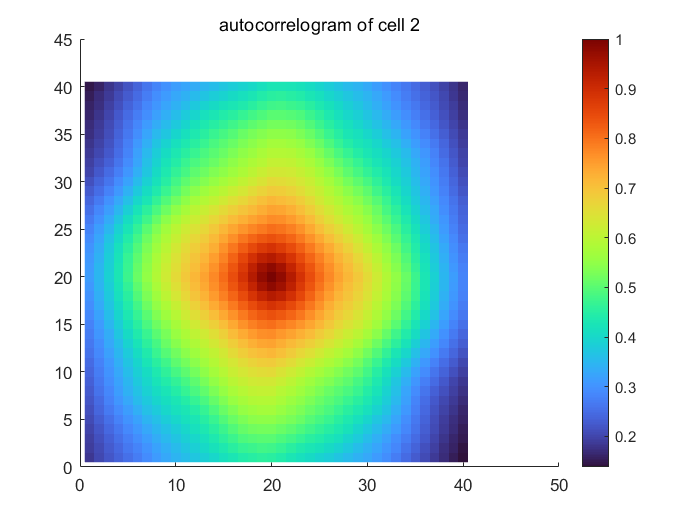

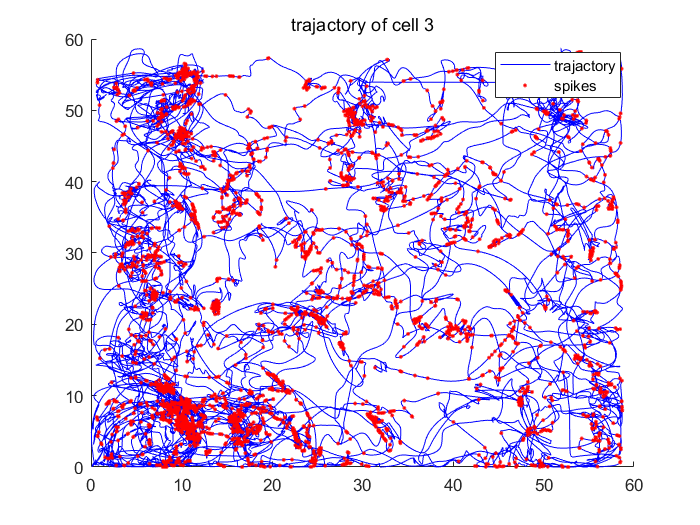

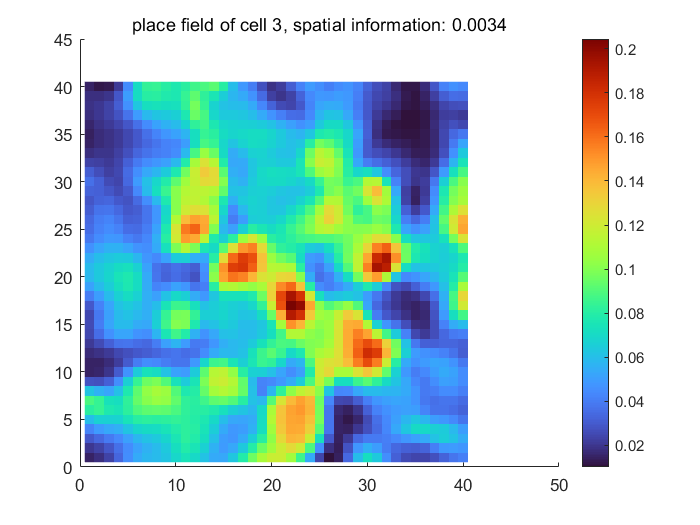

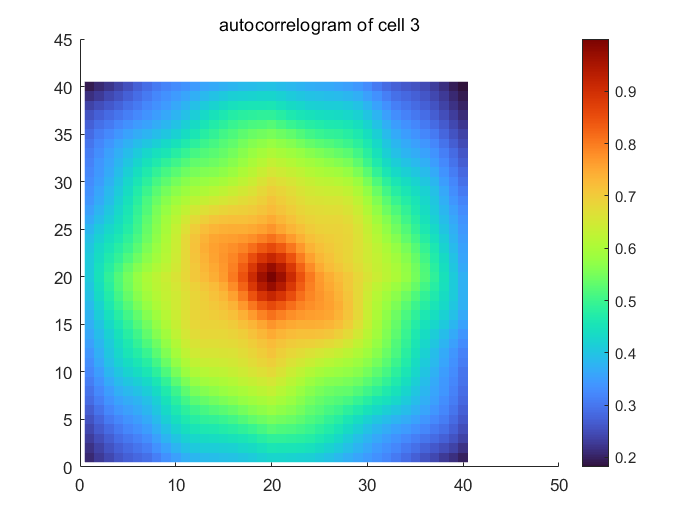

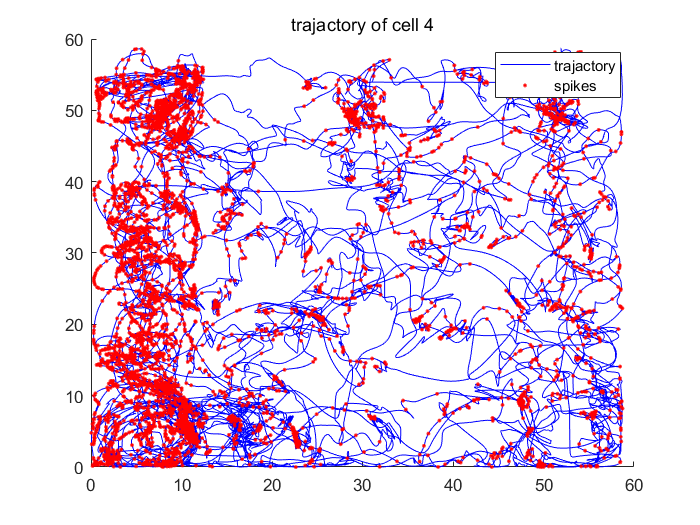

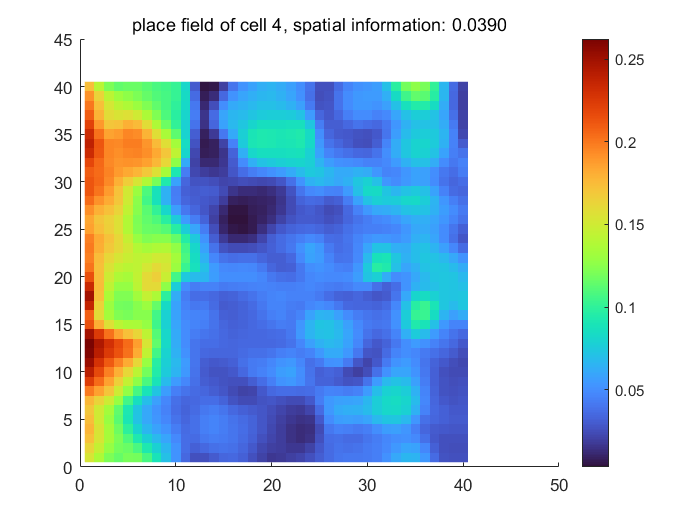

for i = 1:9
    rm = lib.Rate_Matrix(i,pos.pos(:,1),pos.pos(:,2),pos.pos(:,3),all_spk.spks{i,1});
    rm.gauss_rm(40);
    rm.cal_auto_corr();
    lib.Rate_Matrix.plot_trajactory(rm)
    lib.Rate_Matrix.plot_rate_map(rm)
    lib.Rate_Matrix.plot_auto_corr(rm)
end

all_spk = load("./mouse59/mouse59_grid_cell/day09-1118/s1/all_spk.mat");
pos_corr = load("./mouse59/mouse59_grid_cell/day09-1118/s1/m59_d9_s1_spks_pfield_pos_corr.mat");
pos = load("./mouse59/mouse59_grid_cell/day09-1118/s1/pos.mat");
for i = 1:9
    rm = lib.Rate_Matrix(i,pos.pos(:,1),pos.pos(:,2),pos.pos(:,3),all_spk.spks{i,1});
    rm.gauss_rm(40);
    rm.cal_auto_corr();
    lib.Rate_Matrix.plot_trajactory(rm)
    lib.Rate_Matrix.plot_rate_map(rm)
    lib.Rate_Matrix.plot_auto_corr(rm)
end